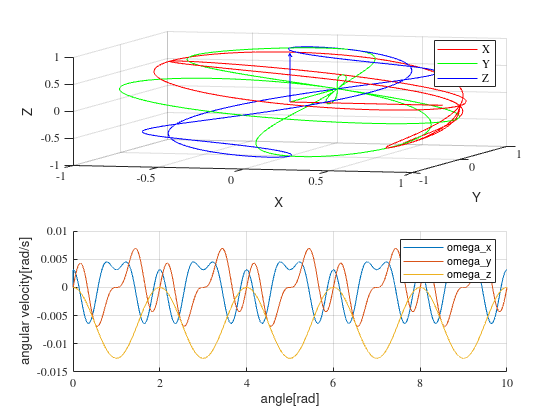

% Right-Invariant EKF localization on SE(2). The process model 
% is simply X_k+1 = X_k * exp(u_k + w_k) where
% X_k is in SE(2), u_k is the twist in se(2), and w_k is N(0,Q_k) and defined 
% in the Lie algebra se(2). The measurements are noisy 2D coordinates of the
% landmarks in Cartesian plane. We use expm and logm as numerical Lie exp 
% and log map. Both maps have closed-form formulas as well.
%
%   Author: Maani Ghaffari Jadidi
%   Date:   03/12/2020

clc; clear; close all

% incremental visualization
green = [0.2980 .6 0];
crimson = [220,20,60]/255; 
darkblue = [0 .2 .4];
Darkgrey = [.25 .25 .25];
VermillionRed = [156,31,46]/255;
DupontGray = [144,131,118]/255;

fsize = 14; % font size
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');

angle = 0:0.001:10;

v = @(x) [cos(x),sin(x),0];

%%Vector of oruentations
H = cell(length(angle));
%%Vector of corresponding lie algebra elements
u = cell(length(angle));
H{1} = eye(3);%Initial conditions


%%Unit vectors for visualizations
X = [ones(1,length(angle));
     zeros(2,length(angle))];
Y = [zeros(1,length(angle));
     ones(1,length(angle));
     zeros(1,length(angle))];
Z = [zeros(2,length(angle));
    ones(1,length(angle))];
%% Vector of angular velocities
omega = zeros(3,length(angle));

for i = 1:length(angle)
    %Generate trajectories based on the Rodrigues formula
    H{i} = Rod((angle(i))*2*pi*0.5  ,v(angle(i)*2*pi ));
    X(:,i) = H{i}*X(:,i);
    Y(:,i) = H{i}*Y(:,i);
    Z(:,i) = H{i}*Z(:,i);
    if(i > 1)
        %TODO 
        %create mesurements, mind the coordinate frames
        u{i} = logm(H{i-1}\H{i});
        omega(:,i) = [-u{i}(2,3),u{i}(1,3), -u{i}(1,2)];
    end
end

%%Plot of how the coordinates change under our SO(3) trajectory
%%and angular velocities over time
vis(X,Y,Z,omega,angle)




len = length(angle)

len = 10001


% construct noise free motion trajectory (sanity check for the generated
% inputs!)
path = [];
path.T = H{1};
for i = 2:size(u,1)
   %% TODO
   %%Integrate the noiseless trajectory, plot both and see if 
end


 %TODO
 % build a system 
 sys = [];
 % motion model noise covariance
 sys.X = zeros(3);
 sys.Q = zeros(3);

Incorrect use of '=' operator. Assign a value to a variable using '=' and compare values for equality using '=='.

 sys.A = zeros(3);
 sys.f = zeros(3);
 sys.H = zeros(3);
 sys.N = zeros(3);

%%%%%%%%
% DUPA %
%%%%%%%%




% % so(3) Lie algebra basis twist 
            Gox = [0     0     0  ;
                   0     0     -1  ;
                   0     1     0   ]; % omega_x
            
            Goy = [0     0     1   ;
                   0     0     0   ;
                   -1     0     0  ]; % omega_y

            Goz = [0     -1     0  ;
                   1     0     0   ;
                   0     0     0   ]; % omega_z
 

% % now make the twist noisy! in practice the velocity readings are not
% % perfect.
u_n=cell(len);
u_n{1}=zeros(3);
for i = 1:length(u)
    noise = sys.Q* randn(3,1);
    N = Gox * noise(1) + Goy * noise(2) + Goz * noise(3);
    u_n{i} = u{i} + N;
end

path_noisy = [];
path_noisy.T = H{1};
for i = 1:size(u,1)
    %TODO 
    %integrate n Noisy measurements
    path_noisy.T(i) =  zeros(3,3);
end



%%Visualize
%%use the vis function used before




 filter = riekf_SE3(sys); % create an RI-EKF object

 % plot initial mean 

% video recorder object
% video = VideoWriter('dead-reckoning_se2.avi', 'Motion JPEG AVI');
% view(90,0)
% 
% video = VideoWriter('riekf_localization_se2.avi', 'Motion JPEG AVI');
% video.Quality = 100;
% open(video)

%TODO 
%choose measurement frequencies
%units depend on how you discretise the trajectory
skip_mag = 10000000;
skip_acc = 10000000;

path_filter = [];
path_filter.T = H{1};

 h_leg{4} = plot3(path_filter.x,path_filter.y,path_filter.z);

for i = 1:size(u,1)
    % predict next pose using given twist
    filter.prediction(u_n{i});

    if ~mod(i,skip_mag)
        %TODO 
        %implement magnetometer correction step
    end

    if ~mod(i,skip_acc)
        %TODO
        %implement accelerometer correction step
    end

    path_filter.x(i+1) = filter.X(1,5);
    path_filter.y(i+1) = filter.X(2,5);
    path_filter.z(i+1) = filter.X(3,5);
    path_filter.vx(i+1) = filter.X(1,4);
    path_filter.vy(i+1) = filter.X(2,4);
    path_filter.vz(i+1) = filter.X(3,4);

   % update graphics
    set(h_leg{2},'XData',filter.X(1,5),'YData', filter.X(2,5),'ZData', filter.X(3,5));
    set(h_leg{3},'XData',filter.X(1,5),'YData', filter.X(2,5),'ZData', filter.X(3,5), 'UData', filter.X(1,4), 'VData', filter.X(2,4), 'WData', filter.X(3,4));
    set(h_leg{4},'XData',path_filter.x,'YData', path_filter.y,'ZData', path_filter.z);

     %drawnow 
     %pause(0.0001)
    %  frame = getframe(gcf);
    % writeVideo(video,frame);
end


% close(video)

% figuresize(21,21,'cm')
% print -opengl -dpng -r600 riekf_loc_se2.png
% figuresize(21,21,'cm')
% print -opengl -dpng -r600 riekf_loc_se2.png


function H = posemat_SE_2(x,y,h)
% construct a SE(2) matrix element
H = [cos(h) -sin(h) x;
    sin(h)  cos(h)  y;
    0       0       1];
end




function fx = fx(x,u)
    %%TODO
    %define state change function
    %e.g. system dynamics, x_{k+1} = f(x_k,u)
end